# Lab 5 report

12210309 LI Zhiying

v = linspace(0, 1, 256)';
colormap([v v v]);

## Problem1 - Image stretching

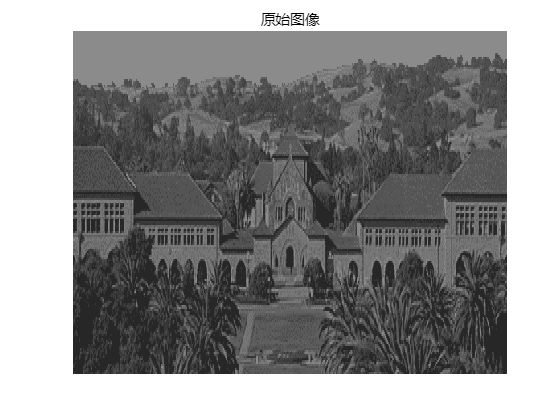

% i. 显示原始图像
f1 = fopen('lab5prob1data');
a1 = fread(f1,[540,inf],'uint8');
Img1 = a1';
image(Img1);
axis off;
title('原始图像');


% brightness
brightness = mean(Img1(:));
% contrast
contrast = std(Img1(:));

fprintf('原始图像的亮度: %.2f, 对比度: %.2f\n', brightness, contrast);

原始图像的亮度: 86.17, 对比度: 31.34


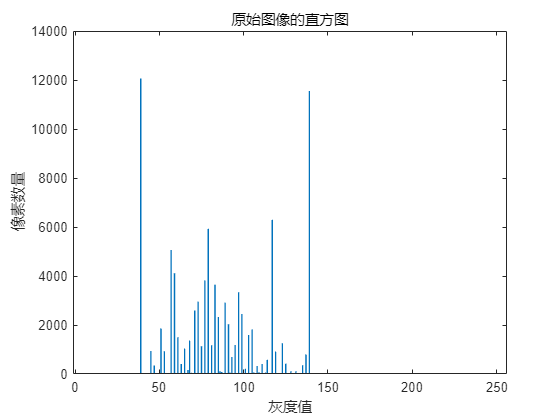



% ii. 计算直方图
histogram = zeros(256,1);

for i = 1:256
    histogram(i) = sum(Img1(:) == i);  % 统计每个灰度值的出现次数
end

figure;
bar(0:255, histogram);
title('原始图像的直方图');
xlabel('灰度值');
ylabel('像素数量');

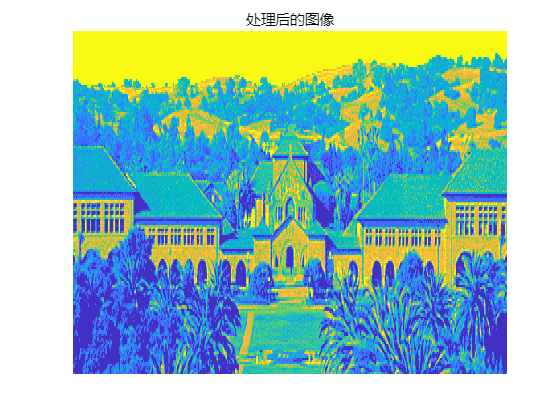


meanImage = mean(Img1(:));
stdImage = std((Img1(:)));

% iii. 拉伸图像
targetMean = 128;
targetStd = 80;

scaleFactor = targetStd / stdImage;
shiftValue = targetMean - meanImage * scaleFactor;

stretchedImage = scaleFactor * double(Img1) + shiftValue;

stretchedImage = min(max(stretchedImage, 0), 255);
stretchedImage = uint8(stretchedImage);  

figure;
image(stretchedImage);
axis off;
title('处理后的图像');

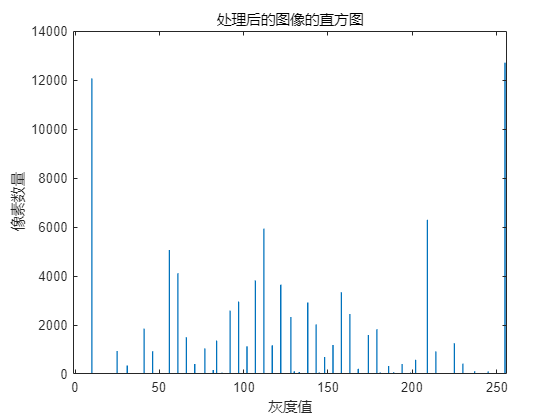


newHistogram = zeros(256, 1);
for i = 0:255
    newHistogram(i+1) = sum(stretchedImage(:) == i);
end

figure;
bar(0:255, newHistogram);
title('处理后的图像的直方图');
xlabel('灰度值');
ylabel('像素数量');


newBrightness = mean(stretchedImage(:));
newContrast = std(double(stretchedImage(:)));
fprintf('处理后图像的亮度: %.2f, 对比度: %.2f\n', newBrightness, newContrast);

处理后图像的亮度: 126.60, 对比度: 77.80


## Problem 2  - More stretching

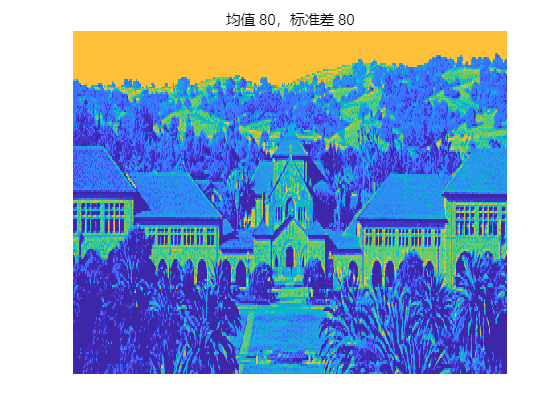

f2 = fopen('lab5prob1data');
a2 = fread(f2,[540,inf],'uint8');
Img2 = a2';

% i. 拉伸图像，均值 80，标准差 80
stretchedImage1 = stretchImage(Img2, 80, 80);
figure;
image(stretchedImage1);
axis off;
title('均值 80，标准差 80');

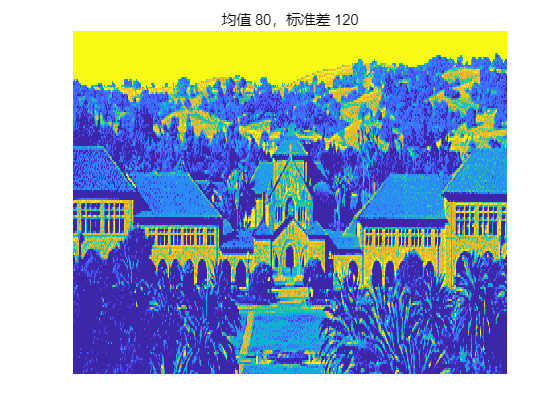


% ii. 拉伸图像，均值 80，标准差 120
stretchedImage2 = stretchImage(Img2, 80, 120);
figure;
image(stretchedImage2);
axis off;
title('均值 80，标准差 120');

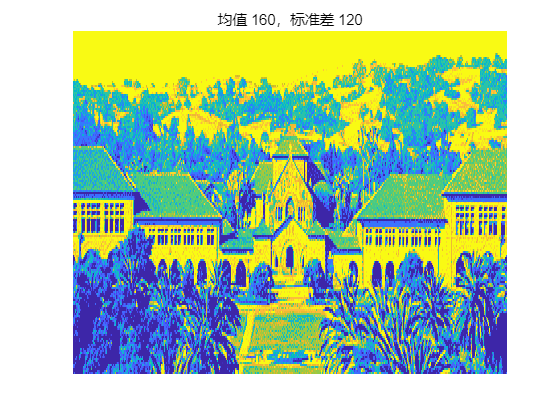


% iii. 拉伸图像，均值 160，标准差 120
stretchedImage3 = stretchImage(Img2, 160, 120);
figure;
image(stretchedImage3);
axis off;
title('均值 160，标准差 120');

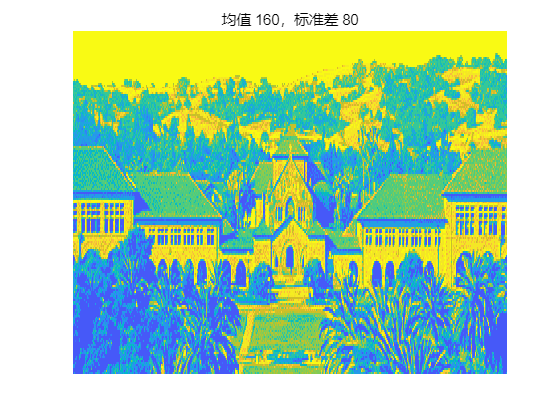


% iv. 拉伸图像，均值 160，标准差 80
stretchedImage4 = stretchImage(Img2, 160, 80);
figure;
image(stretchedImage4);
axis off;
title('均值 160，标准差 80');

*Answer: *均值80，标准差120的拉伸最美观

## Problem 3 - Equalization stretches.

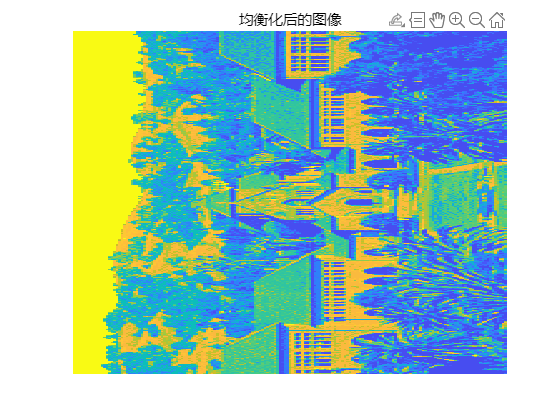

f3 = fopen('lab5prob1data');
a3 = fread(f3,[540,inf],'uint8');
[histogram, grayLevels] = histcounts(a3, 0:256); 
cdf = cumsum(histogram) / sum(histogram); 
equalizedImage = uint8(255 * cdf(double(a3) + 1));
figure;
image(equalizedImage);
axis off;
title('均衡化后的图像');

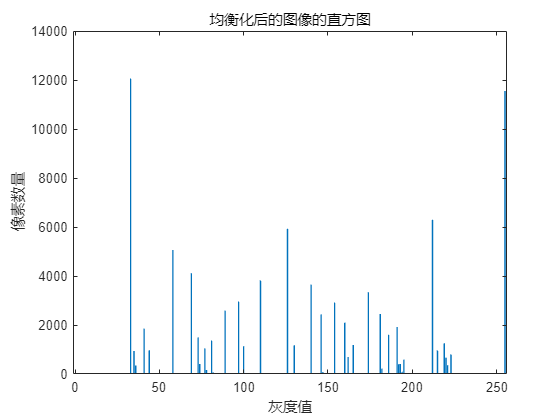

newHistogram = zeros(256, 1);
for i = 0:255
    newHistogram(i+1) = sum(equalizedImage(:) == i);
end

figure;
bar(0:255, newHistogram);
title('均衡化后的图像的直方图');
xlabel('灰度值');
ylabel('像素数量');

## Problem 4 - Nonlinear stretches 

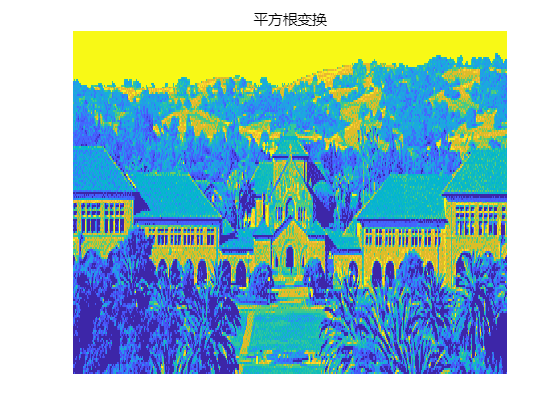

f4 = fopen('lab5prob4data');
a4 = fread(f4,[540,inf],'uint8');
img4 = a4';

% i. 处理平方根
sqrtImage = powerTransform(img4, 1/2);
figure;
image(sqrtImage);
axis off;
title('平方根变换');

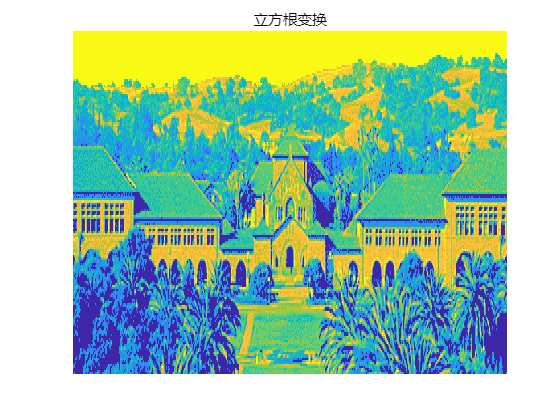


% ii. 处理立方根
cbrtImage = powerTransform(img4, 1/3);
figure;
image(cbrtImage);
axis off;
title('立方根变换');

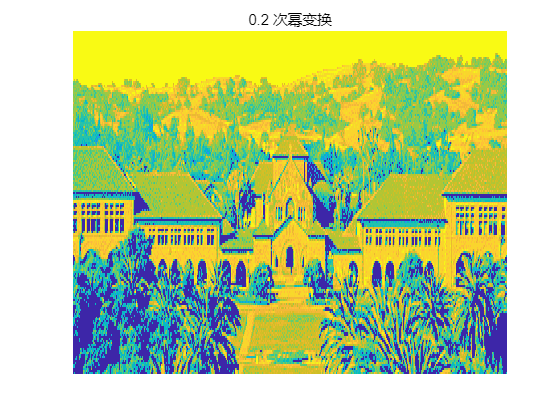


% iii. 处理 0.2 次幂
power02Image = powerTransform(img4, 0.2);
figure;
image(power02Image);
axis off;
title('0.2 次幂变换');

*Answer: *平方根变换更美观

function stretchedImage = stretchImage(imageData, targetMean, targetStd)
    meanImage = mean(imageData(:));
    stdImage = std(double(imageData(:)));

    scaleFactor = targetStd / stdImage;
    shiftValue = targetMean - meanImage * scaleFactor;

    stretchedImage = scaleFactor * double(imageData) + shiftValue;
    
    stretchedImage = min(max(stretchedImage, 0), 255);
    stretchedImage = uint8(stretchedImage);
end

function transformedImage = powerTransform(imageData, power)

    normalizedImage = double(imageData) / 255;

    transformedImage = normalizedImage .^ power;

    transformedImage = uint8(transformedImage * 255);
end